 it     |f(x)|
 0    29.563491
     alpha       |f(x)|
     1.0000     6.369879
 1     6.369879
     alpha       |f(x)|
     1.0000     1.014043
 2     1.014043
     alpha       |f(x)|
     1.0000     0.091767
 3     0.091767
     alpha       |f(x)|
     1.0000     0.002099
 4     0.002099
     alpha       |f(x)|
     1.0000     0.000002
 5     0.000002
     alpha       |f(x)|
     1.0000     0.000000
 6     0.000000
     alpha       |f(x)|
     1.0000     0.000000
 7     0.000000
 SUCCESS: Converged


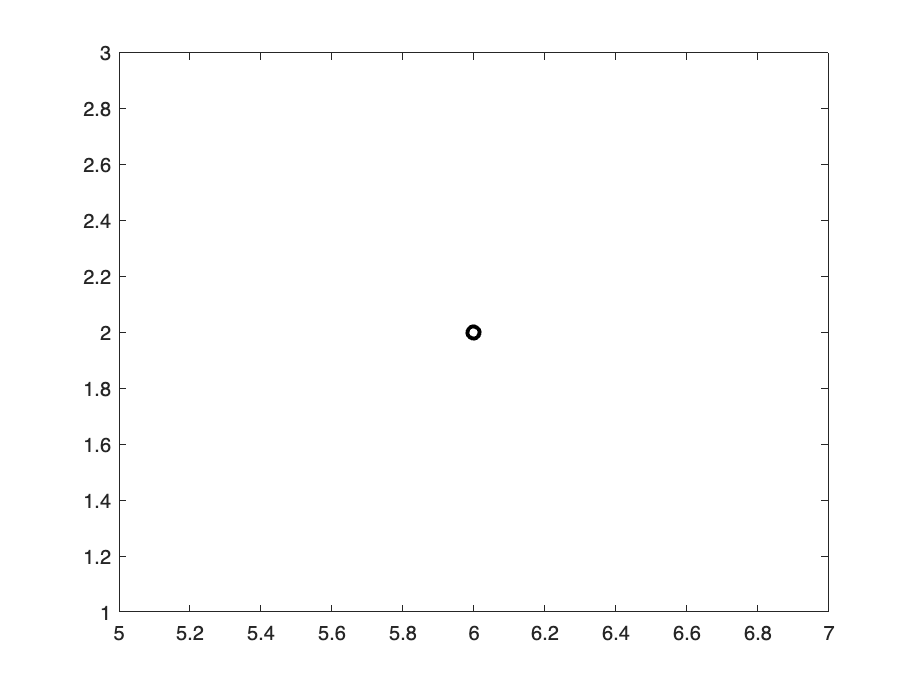

% 主代码
% 设置参数和初始条件
V = 1.0;
G = 45.0;
k = 0.7;
a0 = 6.0;
initial_guess = [5; 4; 3; 2; 1];
tol = 1e-12;
max_iterations = 500;

% 定义非线性系统函数句柄
fnon = @(x, beta, k, G) nonlinear_equations(x, beta, k, G);

% 定义雅可比矩阵函数句柄
fjac = @(n, x, f, fnon, beta, k, G) calculateJacobian(n, x, f, fnon, beta, k, G);

% 设置 beta 参数
beta = 1/V;

% 调用 Newton's method with line-search
[x, f] = newtonSysL(fnon, fjac, [a0; initial_guess], tol, max_iterations, beta, k, G);


% 输出结果
fprintf('Number of Newton iterations: %d\n', length(f)-1);

Number of Newton iterations: 4


fprintf('Numerical solution vector: [');

Numerical solution vector: [

fprintf('%f, ', x);

6.000000, 2.000000, 1.000000, 0.618034, 0.431683, 0.325641, 

fprintf(']\n');

]
